Datos cargados: 288 registros


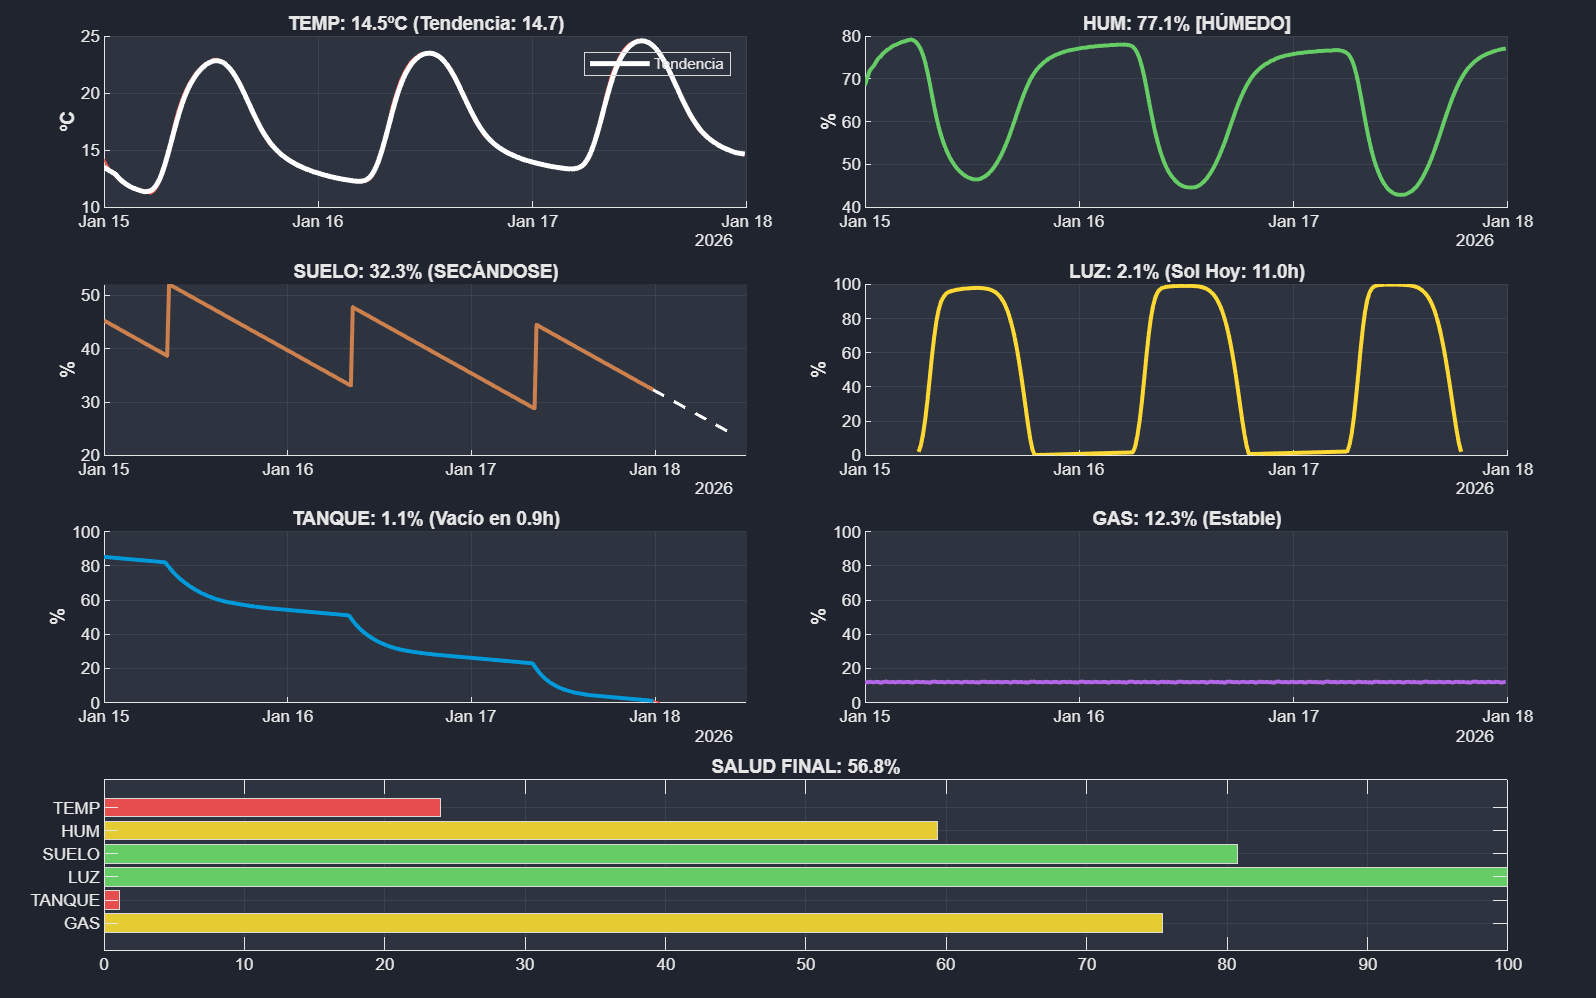

% --- LIMPIEZA INICIAL OBLIGATORIA ---
close all; clear; clc;

% Cargar credenciales
raw = fileread('./infra/matlab/secrets_og.json');
settings = jsondecode(raw);
channelID = settings.channelID;
readKey = settings.readAPIKey;

%% CONFIGURACIÓN DE ARCHIVO HISTÓRICO
csv_filename = 'greenhouse_historico.csv';

T_historico = [];
if isfile(csv_filename)
    try
        opts = detectImportOptions(csv_filename);
        opts.VariableNamingRule = 'preserve';
        T_historico = readtable(csv_filename, opts);
        
        % Mapeo de nombres para asegurar compatibilidad
        mapa_nombres = {
            'Timestamp', 'Time'; 'Temp_C', 'Temp'; 'HumAmb_Pct', 'HumAmb';
            'HumSuelo_Pct', 'HumSuelo'; 'Luz_Pct', 'Luz'; 'Tanque_Pct', 'Tanque'; 'Gas_Pct', 'Gas'
        };
        for k = 1:size(mapa_nombres, 1)
            if ismember(mapa_nombres{k,1}, T_historico.Properties.VariableNames)
                T_historico.Properties.VariableNames{mapa_nombres{k,1}} = mapa_nombres{k,2};
            end
        end
    catch
        T_historico = [];
    end
end

%% CONFIGURACIÓN ESTÉTICA
bg_color = [0.12 0.14 0.18];
ax_color = [0.18 0.20 0.25];
grid_color = [0.30 0.35 0.40];
text_color = [0.90 0.90 0.90];
accent_colors = {[0.95 0.35 0.30],[0.40 0.80 0.40],[0.80 0.50 0.30],[1.00 0.85 0.20],[0.00 0.60 0.85],[0.70 0.40 0.90]};

%% INICIALIZACIÓN DE FIGURA
fig = figure('Color', bg_color, 'Position', [50, 50, 1600, 1000], ...
    'Name', 'GREENHOUSE SMART MONITOR v3.0', 'NumberTitle', 'off', 'MenuBar', 'none'); 

t = tiledlayout(4, 2, 'Padding', 'compact', 'TileSpacing', 'compact');

%% DEFINICIÓN DE INTERFAZ
titles = {'TEMPERATURA', 'HUMEDAD AMB.', 'HUMEDAD SUELO', 'LUZ', 'NIVEL TANQUE', 'CALIDAD AIRE (GAS)'};
units = {'ºC', '%', '%', '%', '%', '%'};
axes_handles = gobjects(6,1);
plot_handles = gobjects(6,1);
extra_plots = gobjects(6,1); % Para líneas de tendencia/predicción

for i = 1:6
    axes_handles(i) = nexttile;
    hold(axes_handles(i), 'on');
    plot_handles(i) = plot(NaT, NaN, 'Color', accent_colors{i}, 'LineWidth', 1.5);
    extra_plots(i) = plot(NaT, NaN, '--', 'Color', [1 1 1 0.5], 'LineWidth', 1.5);
    title(titles{i}); ylabel(units{i});
    if i >= 4, ylim(axes_handles(i), [0 100]); end 
end

% Panel de Salud (Sustituye a la correlación)
ax_health = nexttile([1 2]);
h_bar = barh(ax_health, 1:6, zeros(1,6), 'FaceColor', 'flat');
set(ax_health, 'YTick', 1:6, 'YTickLabel', {'GAS','TANQUE','LUZ','SUELO','HUM','TEMP'});
xlim(ax_health, [0 100]); title('ESTADO DE SALUD DEL SISTEMA');

% Estilo Global Inicial
set(findall(fig, 'type', 'axes'), 'Color', ax_color, 'XColor', text_color, 'YColor', text_color, ...
    'GridColor', grid_color, 'GridAlpha', 0.4, 'XGrid', 'on', 'YGrid', 'on');

%% BUCLE PRINCIPAL
while ishandle(fig)
    try
        % 1. LECTURA DE DATOS
        [data, time] = thingSpeakRead(channelID, 'ReadKey', readKey, 'NumPoints', 60, 'Timeout', 30);

        if ~isempty(data)
            T_new = array2table(data, 'VariableNames', {'Temp', 'HumAmb', 'HumSuelo', 'Luz', 'Tanque', 'Gas'});
            T_new.Time = time;

            % 2. LIMPIEZA
            vars = {'Temp', 'HumAmb', 'HumSuelo', 'Luz', 'Tanque', 'Gas'};
            for v = vars
                col = T_new.(v{1});
                col(col == 0) = NaN; 
                if ~strcmp(v{1}, 'Temp'), col(col > 100) = NaN; end
                T_new.(v{1}) = col;
            end

            % 3. MERGE CON HISTÓRICO Y GUARDADO
            if ~isempty(T_historico)
                T_combined = [T_historico; T_new];
                [~, idx] = unique(T_combined.Time, 'stable');
                T_combined = T_combined(idx, :);
            else
                T_combined = T_new;
            end
            
            % Guardar último dato en CSV
            try
                ult = T_new(end, :);
                fid = fopen(csv_filename, 'a');
                if ftell(fid) == 0 % Si archivo nuevo, poner cabecera
                     fprintf(fid, 'Timestamp,Temp_C,HumAmb_Pct,HumSuelo_Pct,Luz_Pct,Tanque_Pct,Gas_Pct\n');
                end
                vals = table2array(ult(:,1:6)); vals(isnan(vals)) = 0;
                fprintf(fid, '%s,%.2f,%.2f,%.2f,%.2f,%.2f,%.2f\n', datestr(ult.Time, 'yyyy-mm-dd HH:MM:SS'), vals);
                fclose(fid);
            catch; end

            % 4. CÁLCULO DE PARÁMETROS DE TIEMPO
            if height(T_combined) > 1
                dt_min = minutes(mean(diff(T_combined.Time)));
            else
                dt_min = 15;
            end
            if isnan(dt_min), dt_min = 15; end

            % 5. ACTUALIZACIÓN DE GRÁFICAS (LÓGICA CÓDIGO B)
            for i = 1:6
                ax = axes_handles(i);
                h_p = plot_handles(i);
                h_e = extra_plots(i);
                
                y_all = T_combined.(vars{i});
                x_all = T_combined.Time;
                valid = ~isnan(y_all);
                xv = x_all(valid); yv = y_all(valid);
                
                if isempty(yv), continue; end
                val = yv(end);
                set(h_p, 'XData', xv, 'YData', yv);

                switch i
                    case 1 % TEMP: Tendencia
                        y_smooth = movmean(yv, 10);
                        set(h_e, 'XData', xv, 'YData', y_smooth, 'Color', [1 1 1]);
                        title(ax, sprintf('TEMP: %.1fºC (Tendencia: %.1f)', val, y_smooth(end)));
                    
                    case 2 % HUM: Semáforo
                        min_i = 40; max_i = 60;
                        if val < min_i, st = 'SECO'; c = [0.9 0.5 0.2];
                        elseif val > max_i, st = 'HÚMEDO'; c = [0.4 0.6 0.9];
                        else, st = 'PERFECTO'; c = [0.4 0.9 0.4];
                        end
                        title(ax, sprintf('HUM: %.1f%% [%s]', val, st), 'Color', c);
                    
                    case 3 % SUELO: Estado
                        if length(yv) > 5
                            p = polyfit((1:length(yv))', yv, 1);
                            set(h_e, 'XData', [xv(end), xv(end)+minutes(40*dt_min)], 'YData', [val, val+(p(1)*40)]);
                            if p(1) < -0.01, st = 'SECÁNDOSE'; elseif p(1) > 0.01, st = 'SUBIENDO'; else, st = 'ESTABLE'; end
                            title(ax, sprintf('SUELO: %.1f%% (%s)', val, st));
                        end

                    case 4 % LUZ: Acumulado hoy
                        last_day = dateshift(xv(end), 'start', 'day');
                        idx_h = xv >= last_day;
                        sun_h = sum(yv(idx_h) > 30) * (dt_min/60);
                        title(ax, sprintf('LUZ: %.1f%% (Sol Hoy: %.1fh)', val, sun_h));

                    case 5 % TANQUE: Predicción de vaciado
                        saltos = diff(yv); idx_r = find(saltos > 5);
                        i_start = 1; if ~isempty(idx_r), i_start = idx_r(end); end
                        y_ciclo = yv(i_start:end);
                        if length(y_ciclo) >= 3
                            p = polyfit((1:length(y_ciclo))', y_ciclo, 1);
                            if p(1) < -0.01
                                h_rest = (-val/p(1) * dt_min)/60;
                                set(h_e, 'XData', [xv(end), xv(end)+hours(h_rest)], 'YData', [val, 0], 'Color', [1 0.3 0.3]);
                                title(ax, sprintf('TANQUE: %.1f%% (Vacío en %.1fh)', val, h_rest), 'Color', [1 0.6 0.6]);
                            else
                                set(h_e, 'XData', NaT, 'YData', NaN);
                                title(ax, sprintf('TANQUE: %.1f%%', val));
                            end
                        end

                    case 6 % GAS: Alerta subida
                        if length(yv) > 5
                            slope = mean(diff(yv(end-5:end)));
                            if slope > 0.5, title(ax, 'GAS: ¡ALERTA SUBIDA!', 'Color', [1 0.2 0.2]);
                            else, title(ax, sprintf('GAS: %.1f%% (Estable)', val)); end
                        end
                end
            end

            % 6. PANEL DE SALUD (LÓGICA CÓDIGO B)
            % Re-calculamos horas de sol para el score
            last_day = dateshift(T_combined.Time(end), 'start', 'day');
            sun_h = sum(T_combined.Luz(T_combined.Time >= last_day) > 30, 'omitnan') * (dt_min/60);
            
            sc_temp = max(0, 100 - abs(T_combined.Temp(end) - 24) * 8);
            sc_hum  = max(0, 100 - abs(T_combined.HumAmb(end) - 50) * 1.5);
            sc_suelo = min(100, (T_combined.HumSuelo(end)/40)*100);
            sc_luz = min(100, sun_h * 12.5); % 8h = 100%
            sc_tanq = T_combined.Tanque(end);
            sc_gas = max(0, 100 - (T_combined.Gas(end) * 2));
            
            scores = [sc_gas, sc_tanq, sc_luz, sc_suelo, sc_hum, sc_temp];
            h_bar.YData = scores;
            
            % Colores de las barras
            cdata = zeros(6,3);
            for k = 1:6
                if scores(k) > 80, cdata(k,:) = [0.4 0.8 0.4];
                elseif scores(k) > 50, cdata(k,:) = [0.9 0.8 0.2];
                else, cdata(k,:) = [0.9 0.3 0.3]; end
            end
            h_bar.CData = cdata;
            title(ax_health, sprintf('SALUD FINAL DEL SISTEMA: %.1f%%', mean(scores)), 'Color', text_color);

            drawnow limitrate;
            fprintf('[%s] Datos actualizados. Salud: %.1f%%\n', datestr(now, 'HH:MM:SS'), mean(scores));
        end
    catch ME
        fprintf('Error en bucle: %s\n', ME.message);
    end
    pause(15);
end